# Aufgabe 3 (Pulsbreite eines Femtosekundenlasers)

(weitere Erklärungen zum Hintergrund dieser Aufgabe gibt’s vor Ort beim Praktikum.)

Femtosekundenlaser erzeugen Lichtpulse, die nur wenige Femtosekunden dauern (1 Femtosekunde =${10}^{-15}$ Sekunden) und haben viele Anwendungen in Wissenschaft und Technik. Um die Form eines solchen Lichtpulses genauer zu bestimmen, wird oft die *FROG*-Technik genutzt, bei der die Autokorrelation des Lichtpulses im Frequenzbereich gemessen wird. Im Ordner `Daten/FrogTraces` befindet sich eine Sammlung sogenannter *Frog*-Traces. Dabei handelt es sich um Spektrogramme der Autokorrelation von kurzen Laserpulsen.

Der interessierte Leser findet hier weitere Informationen: [https://uol.de/f/5/inst/physik/ag/ukd/Publikationen/2007/Skript-Version30.pdf.](https://uol.de/f/5/inst/physik/ag/ukd/Publikationen/2007/Skript-Version30.pdf.) Ab Seite 70 werden die Frog-Traces für einige Pulsformen dargestellt. 

In dieser Aufgabe geht es darum, ein vollverbundenes Netz zu entwickeln, das die Pulsbreite anhand des Spektrogramms des Pulses vorhersagt. Die Pulsbreite für jedes Spektrogramm ist in den Dateien `MetaDataTrain.csv` und `MetaDataTest.csv `gegeben.

### Aufgabe 3 (a) Daten laden

Laden Sie die Trainingsdaten und bringen Sie sie in eine für vollverbundene Netze geeignete Form.

dataDir = fullfile('Daten', 'FrogTraces'); 
trainDir = fullfile(dataDir, 'train');
testDir = fullfile(dataDir, 'test');
metaDataTrain = readtable(fullfile(trainDir, 'MetaDataTrain.csv'));
metaDataTest = readtable(fullfile(testDir, 'MetaDataTest.csv'));
nTrain = size(metaDataTrain, 1);
nTest = size(metaDataTest, 1);

Ein Bild laden und ansehen:

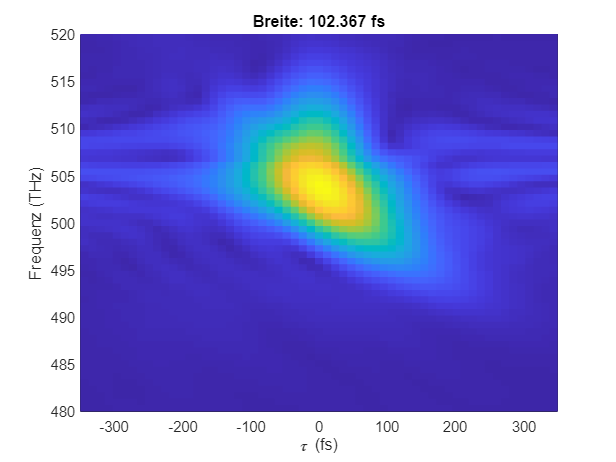

img = imread(fullfile(trainDir, [metaDataTrain.Name{1} '.png']));
imSize = size(img);
pc = pcolor(linspace(-350, 350, imSize(1)), ...
   linspace(480, 520, imSize(2)), img);
pc.LineStyle='none';
title(sprintf('Breite: %.3f fs', metaDataTrain.RMSWidth(1)));
xlabel('\tau (fs)');
ylabel('Frequenz (THz)');

Trainingsdaten einlesen:

trainMat = zeros(imSize(1),imSize(2),1,nTrain);

for i = 1:nTrain
   img = imread(fullfile(trainDir, [metaDataTrain.Name{i} '.png']));
   trainMat(:,:,1,i) = img;
end
% Zielgroessen aus Tabelle holen:
trainTarget = metaDataTrain.RMSWidth;

testMat = zeros(60,60,1, nTest);

for i = 1:nTest
   img = imread(fullfile(testDir, [metaDataTest.Name{i} '.png']));
   testMat(:,:,1,i) = img;
end
testTarget = metaDataTest.RMSWidth;


### CNN entwerfen


lambda = 0.0001;
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 32, ...
    'MaxEpochs',150, ...
    'LearnRateSchedule', 'piecewise', ...
    'InitialLearnRate',0.1, ...
    'LearnRateDropPeriod', 25, ...
    'Shuffle','every-epoch', ...
    'Verbose',true, ...
    'OutputNetwork', 'best-validation-loss', ...
    'ValidationData', {testMat, testTarget}, ...
    'Plots','none');

layers = [
    imageInputLayer([60 60 1])
    convolution2dLayer(2, 64, 'Padding', 'same')
    reluLayer
    maxPooling2dLayer(2, "Padding","same", Stride=2)
    convolution2dLayer(3, 128, 'Padding', 'same')
    reluLayer
    maxPooling2dLayer(2, "Padding","same", Stride=2)
    convolution2dLayer(4, 256, 'Padding', 'same')
    reluLayer
    maxPooling2dLayer(2, "Padding","same", Stride=2)
    convolution2dLayer(5, 512, 'Padding', 'same')
    reluLayer
    fullyConnectedLayer(1)
    batchNormalizationLayer
    regressionLayer
];

tic
net_frogtrace = trainNetwork(trainMat, trainTarget, layers, options);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       102.43 |        91.43 |    5246.2344 |    4179.3452 |          0.1000 |
|       1 |          50 |       00:00:00 |        21.37 |        21.89 |     228.3185 |     239.5140 |          0.1000 |
|       2 |         100 |       00:00:01 |        17.75 |        20.41 |     157.5463 |     208.3071 |          0.1000 |
|       3 |         150 |       00:00:01 |        14.75 |        18.53 |     108.7295 |   

toc

Elapsed time is 84.580607 seconds.


### Aufgabe 3 (c) Anwenden auf Testdaten 

Laden Sie die Testdaten und überprüfen Sie damit die Qualität Ihres in Teil (b) entwickelten Netzes.

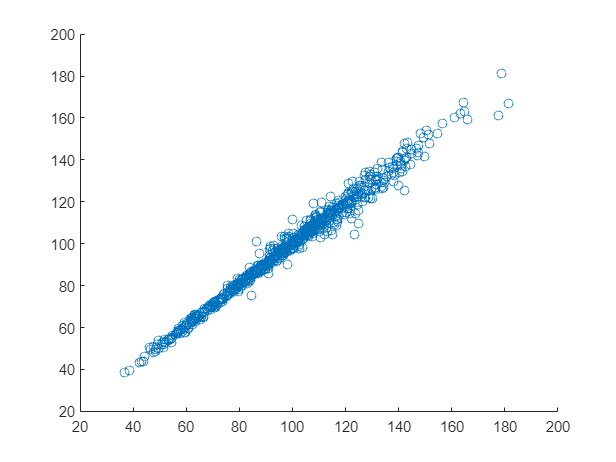


testPred = predict(net, testMat);

scatter(testTarget, testPred);


RMSETest = sqrt(1/nTest * sum( (testTarget - testPred).^2 ))

RMSETest = single
3.1163